# Data preparation: cleaning

The data in "biopsies_raw.csv" has not been cleaned:

clear all;
data = readtable('biopsies_raw.csv');

Clean the data and split it ready for training and testing a classifier.

Marks are available for:

- Appropriately addressing: duplicated examples; irrelevant features; missing values [5 marks]

- Identifying and removing the extreme outlier for the "smoothness_mean" feature [3 marks]

- Splitting the data up into an appropriately named training dataset and testing dataset [8 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

% add as many lines of code as you need below:
summary(data)


Variables:

    id: 570×1 double

        Values:

            Min             8670
            Median    9.0616e+05
            Max       9.1132e+08

    diagnosis: 570×1 cell array of character vectors

    radius_mean: 570×1 double

        Values:

            Min               6.981    
            Median            13.34    
            Max               28.11    
            NumMissing        1        

    texture_mean: 570×1 double

        Values:

            Min             9.71    
            Median        18.835    
            Max            39.28    

    perimeter_mean: 570×1 double

        Values:

            Min            43.79      
            Median         86.21      
            Max            188.5      

    area_mean: 570×1 double

        Values:

            Min          143.5   
            Median      548.75   
            Max           2501   

    


% set the table to only show unique values:
data = unique(data);

% delete the irrelevant 'id' row (will effect the results if left in):
data(:, 'id') = [];

% delete row which has a missing value (NumMissing):
data(isnan(data{:, 'radius_mean'}), :) = [];

summary(data)


Variables:

    diagnosis: 568×1 cell array of character vectors

    radius_mean: 568×1 double

        Values:

            Min           6.981    
            Median       13.355    
            Max           28.11    

    texture_mean: 568×1 double

        Values:

            Min             9.71    
            Median        18.855    
            Max            39.28    

    perimeter_mean: 568×1 double

        Values:

            Min            43.79      
            Median         86.21      
            Max            188.5      

    area_mean: 568×1 double

        Values:

            Min          143.5   
            Median      548.75   
            Max           2501   

    smoothness_mean: 568×1 double

        Values:

            Min            0.05263     
            Median        0.095895     
            Max              0.985     

    compactnes

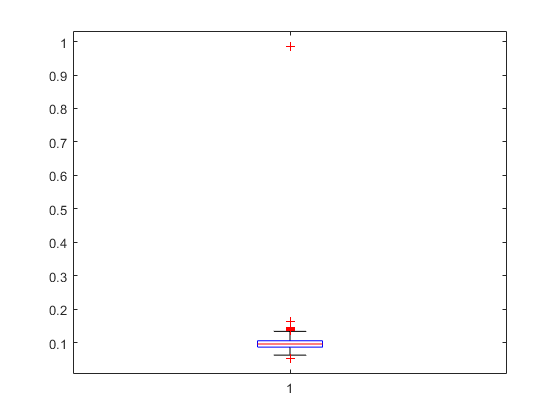


% plot a boxplot to show the outlier:
boxplot(data{:, 'smoothness_mean'})

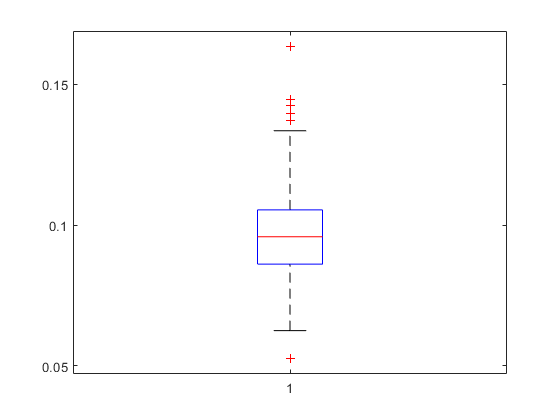

% delete row where outlier is located:
data(149, :) = [];
% check to see if outlier has been removed:
boxplot(data{:, 'smoothness_mean'})


% check size of the data and set rng value:
size(data)

ans =    567    31


rng(1)
% split 25% of the data for testing:
nTest = round(0.25 * size(data, 1))

nTest = 142


% randomize the data:
data_shuffled = data(randperm(size(data, 1)), :);
% store data for testing:
data_test = data_shuffled(1:1:nTest, :);
% store data for training:
data_train = data_shuffled(nTest+1:1:end, :);

% seperate the examples and the labels for the training dataset:
train_labels = categorical(data_train{:, 'diagnosis'});
train_examples = data_train;
train_examples(:, 'diagnosis') = [];
% seperate the examples and the labels for testing dataset:
test_labels = categorical(data_test{:, 'diagnosis'});
test_examples = data_test;
test_examples(:, 'diagnosis') = [];
